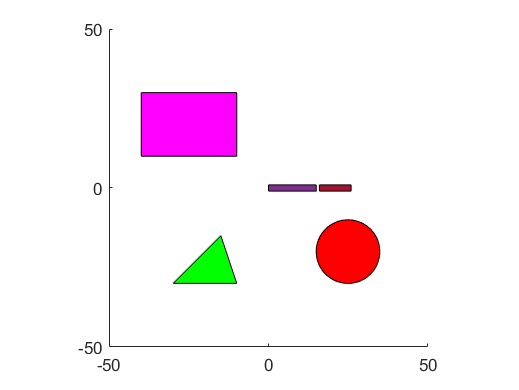

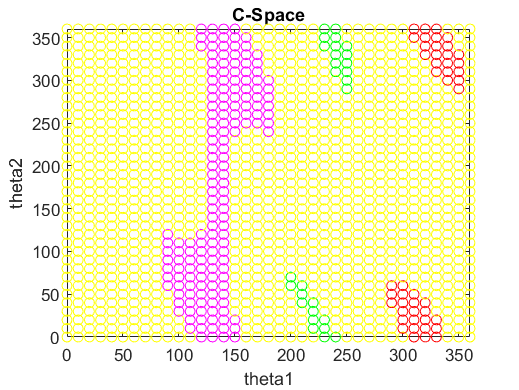

clc; 
clear; 
%link dimesions; 
l1=15; 
l2=10; 
l1_dimension=[0,1;0,-1;15,-1;15,1]; 
l2_dimension=[0,1;0,-1;10,-1;10,1]; 
 
hold on; 
figure(1); 
axis([-50 50 -50 50]); 
daspect([1 1 1]); 
l1_arm=fill(l1_dimension(:,1),l1_dimension(:,2),[0.4940 0.1840 0.5560]); 
l2_arm=fill(l2_dimension(:,1),l2_dimension(:,2),[0.6350 0.0780 0.1840]); 
 
 
%obstacles 
 
%circle 
x_pos=25; 
y_pos=-20; 
r=10; 
t=linspace(1,360,360); 
 
x_component=x_pos+ r*cosd(t); 
y_component=y_pos+ r*sind(t); 
 
 
% rectangle 
rectangle= [-10 10;-10 30;-40 30;-40 10]; 
 
% triangle 
triangle = [-10 -30;-30 -30;-15 -15]; 
 
obs1= polyshape(x_component,y_component); 
obs2=polyshape(rectangle(:,1),rectangle(:,2)); 
obs3=polyshape(triangle(:,1),triangle(:,2)); 
% coloring the Obstacles 
fill(x_component,y_component,'r'); 
fill(rectangle(:,1),rectangle(:,2),'m') 
fill(triangle(:,1),triangle(:,2),'g'); 
hold off; 
 
%you can set resoulution of C-Space, 
resolution1=10; 
resolution2=10; 
 
for tht1=0:resolution1:360 
for tht2=0:resolution2:360 
 x1=l1*cosd(tht1); 
 y1=l1*sind(tht1); 
 
 x2=x1+cosd(tht1+tht2); 
 y2=y1+sind(tht1+tht2); 
 
rotated_arm1=l1_dimension*[cosd(tht1) sind(tht1);-sind(tht1) cosd(tht1)]; 
 
rotated_arm2=l2_dimension*[cosd(tht1+tht2) sind(tht1+tht2);-sind(tht1+tht2)... 
cosd(tht1+tht2)]; 
 
set(l1_arm,'xdata',rotated_arm1(:,1),'ydata',rotated_arm1(:,2)); 
set(l2_arm,'xdata',x2+rotated_arm2(:,1),'ydata',y2+rotated_arm2(:,2)); 
 
arm1=polyshape(rotated_arm1(:,1),rotated_arm1(:,2)); 
arm2=polyshape(x2+rotated_arm2(:,1),y2+rotated_arm2(:,2)); 
 
% check if arm hits any obstacle 
 
hold on 
figure(6); 
xlabel('theta1') 
ylabel('theta2') 
title('C-Space'); 
if(overlaps(arm1,obs1)||overlaps(arm2,obs1)) 
plot(tht1,tht2,'ro'); 
elseif(overlaps(arm1,obs2)||overlaps(arm2,obs2)) 
    plot(tht1,tht2,'mo'); 
elseif(overlaps(arm1,obs3)||overlaps(arm2,obs3)) 
    plot(tht1,tht2,'go'); 
else 
    plot(tht1,tht2,'yo'); 
end 
axis([0 360 0 360]); 
pause(0.0000000001); 
end 
end